clc;
clear all;
close all;
% start from robotics lab folder
addpath(genpath("methods"));% inport metods
addpath(genpath("EA1"));% inport folder with code

Initial parametr

%nominal parameters
r_nom = 0.03;
d_nom = 0.165;
omega_max = 10;
w_max=10;

%time
Ts = 0.04;


%trajectory
R = 0.4;
omega_trj = 2*pi;

%load data
load(fullfile("EA1/robot laboratory/measurements/", 'Tc_30.mat'));%load measure data
w_30=sim_Tc_30.measures.signals.values(:,4:5);
q_30 = sim_Tc_30.measures.signals.values(:,1:3);


%unwrapping and rototraslation to start from 0,0,0
theta=-q_30(1,3);
R_m=[   cos(theta), -sin(theta);
        sin(theta), cos(theta)];
q_30(:,1:2)=(q_30(:,1:2)-q_30(1,1:2))*R_m';
q_30(:,3) = unwrap(q_30(:,3)-q_30(1,3));

load(fullfile("EA1/robot laboratory/measurements/", 'Tc_45.mat'));%load measure data
q_45 = sim_Tc_45.measures.signals.values(:,1:3);

%unwrapping and rototraslation to start from 0,0,0
theta=-q_45(1,3);
R_m=[   cos(theta), -sin(theta);
        sin(theta), cos(theta)];
q_45(:,1:2)=(q_45(:,1:2)-q_45(1,1:2))*R_m';
q_45(:,3) = unwrap(q_45(:,3)-q_45(1,3));

load(fullfile("EA1/robot laboratory/measurements/", 'Tc_18.mat'));%load measure data
q_18 = sim_Tc_18.measures.signals.values(:,1:3);

%unwrapping and rototraslation to start from 0,0,0
theta=-q_18(1,3);
R_m=[   cos(theta), -sin(theta);
        sin(theta), cos(theta)];
q_18(:,1:2)=(q_18(:,1:2)-q_18(1,1:2))*R_m';
q_18(:,3) = unwrap(q_18(:,3)-q_18(1,3));

path

%trajectory
x=@(s) R*sin(2*omega_trj.*s);
y=@(s) R*sin(omega_trj.*s);

%trajectory analitic derivatives
x_dot =@(s) R*2*omega_trj*cos(2*omega_trj*s);
y_dot =@(s) R*omega_trj*cos(omega_trj*s);

x_ddot =@(s) R*4*omega_trj*omega_trj*(-sin(2*omega_trj*s));
y_ddot =@(s) R*omega_trj*omega_trj*(-sin(omega_trj*s));

30

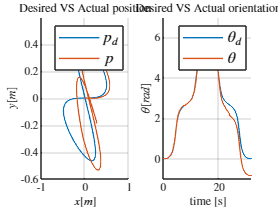

%timelaw
mode = 2;
Ta = 1;
Tc = 30;
total_time = 2*Ta + Tc;
t = 0:Ts:total_time;
[s, s_dot] = time_law_fn(t,total_time,mode,Ta,Tc);

%calculate q_d [x;y;theta] and u [v;w] and prepare it for the sim
[q_d, u] = cartesian_output_2_kin_stateInput(x(s),y(s),x_dot(s),y_dot(s),x_ddot(s),y_ddot(s),s_dot);
%rototraslation to start from 0,0,0
theta=-q_d(3,1);
R_m=[   cos(theta), -sin(theta);
        sin(theta), cos(theta)];
q_d(1:2,:)=R_m*q_d(1:2,:);
q_d(3,:) = q_d(3,:)-q_d(3,1);
q_d_sim=timeseries(q_d',t);
u_sim=timeseries(u',t);%initial value problems

%weel velocities
omega_l_30 = u(1,:)/r_nom-d_nom/(2*r_nom)*u(2,:);
omega_r_30 = u(1,:)/r_nom+d_nom/(2*r_nom)*u(2,:);

%plot
close all
figure(1)

set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(gca,'TickLabelInterpreter','latex');

subplot(1,2,1)
hold on
plot(q_d(1,:), q_d(2,:), 'LineWidth',1)
plot(q_30(:,1), q_30(:,2), 'LineWidth', 1)
hold off
grid on;
title("Desired VS Actual position");
legend({"$p_d$","$p$"}, 'Fontsize',12, 'Location','northeast');
xlabel("$x [m]$", 'interpreter','latex');
ylabel("$y [m]$", 'interpreter','latex');
xlim([-1,1]);
ylim([-0.6,0.6]);

subplot(1,2,2)
hold on
plot(t, q_d(3,:), 'LineWidth', 1)
plot(t, q_30(:,3), 'LineWidth', 1)
hold off
grid on;
title("Desired VS Actual orientation");
legend({"$\theta_d$","$\theta$"}, 'Fontsize',12, 'Location','northeast');
ylabel("$\theta[rad]$", 'interpreter','latex');
xlabel("time [s]", 'interpreter','latex');
ylim([-1,7]);
xlim([0,total_time]);

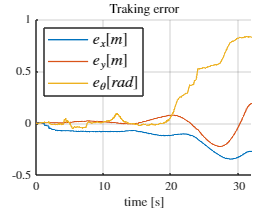

fig = gcf;

%exportgraphics(fig,'plot_p_Tc=30.pdf','ContentType','vector');

%plot errors
figure(2)
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(gca,'TickLabelInterpreter','latex');

hold on
plot(t, q_d(1,:)-q_30(:,1)', 'LineWidth', 1)
plot(t, q_d(2,:)-q_30(:,2)', 'LineWidth', 1)
plot(t, q_d(3,:)-q_30(:,3)', 'LineWidth', 1)
hold off
grid on;
title("Traking error");
legend({"$e_x[m]$","$e_y[m]$", "$e_{\theta}[rad]$"}, 'Fontsize',12, 'Location','northwest');
xlabel("time [s]", 'interpreter','latex');
xlim([0,total_time]);

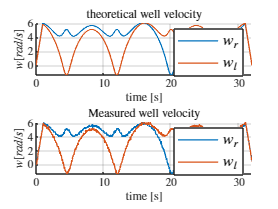



fig = gcf;

%exportgraphics(fig,'plot_e_Tc=30.pdf','ContentType','vector');

%plot velocity of single weels
figure(3)
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(gca,'TickLabelInterpreter','latex');

subplot(2,1,2)
hold on
plot(t, w_30(:,1)', 'LineWidth', 1)
plot(t, w_30(:,2)', 'LineWidth', 1)
hold off
grid on;
title("Measured well velocity");
legend({"$w_r$","$w_l$"}, 'Fontsize',12, 'Location','southeast');
xlabel("time [s]", 'interpreter','latex');
ylabel("$w[rad/s]$",'interpreter','latex');
xlim([0,total_time]);

subplot(2,1,1)
hold on
plot(t, omega_r_30, 'LineWidth', 1)
plot(t, omega_l_30, 'LineWidth', 1)
hold off
grid on;
title("theoretical well velocity");
legend({"$w_r$","$w_l$"}, 'Fontsize',12, 'Location','southeast');
xlabel("time [s]", 'interpreter','latex');
ylabel("$w[rad/s]$",'interpreter','latex');
xlim([0,total_time]);

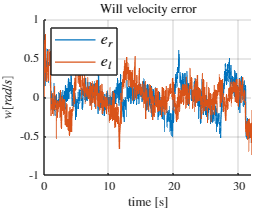



fig = gcf;

%exportgraphics(fig,'plot_whell_Tc=30.pdf','ContentType','vector');

%plot errors
figure(4)
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(gca,'TickLabelInterpreter','latex');

hold on
plot(t, omega_r_30-w_30(:,1)', 'LineWidth', 1)
plot(t, omega_l_30-w_30(:,2)', 'LineWidth', 1)
hold off
grid on;
title("Will velocity error");
legend({"$e_r$","$e_l$"}, 'Fontsize',12, 'Location','northwest');
xlabel("time [s]", 'interpreter','latex');
ylabel("$w[rad/s]$",'interpreter','latex');
xlim([0,total_time]);



fig = gcf;
%exportgraphics(fig,'plot_e_whell_Tc=30.pdf','ContentType','vector');

45

%timelaw
mode = 2;
Ta = 1;
Tc = 45;
total_time = 2*Ta + Tc;
t = 0:Ts:total_time;
[s, s_dot] = time_law_fn(t,total_time,mode,Ta,Tc);

%calculate q_d [x;y;theta] and u [v;w] and prepare it for the sim
[q_d, u] = cartesian_output_2_kin_stateInput(x(s),y(s),x_dot(s),y_dot(s),x_ddot(s),y_ddot(s),s_dot);
%rototraslation to start from 0,0,0
theta=-q_d(3,1);
R_m=[   cos(theta), -sin(theta);
        sin(theta), cos(theta)];
q_d(1:2,:)=R_m*q_d(1:2,:);
q_d(3,:) = q_d(3,:)-q_d(3,1);
q_d_sim=timeseries(q_d',t);
u_sim=timeseries(u',t);%initial value problems

figure(3)

set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(gca,'TickLabelInterpreter','latex');

subplot(1,2,1)
hold on
plot(q_d(1,:), q_d(2,:), 'LineWidth',1)
plot(q_45(:,1), q_45(:,2), 'LineWidth', 1)
hold off
grid on;
xlim([-1,1]);
ylim([-0.5,0.5]);

subplot(1,2,2)
hold on
plot(t, q_d(3,:), 'LineWidth', 1)
plot(t, q_45(:,3), 'LineWidth', 1)
hold off
grid on;
ylim([-1,7]);
xlim([0,total_time]);

%plot errors
figure(4)

set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(gca,'TickLabelInterpreter','latex');

for i=1:3
    subplot(3,1,i)
    plot(t, q_d(i,:)-q_45(:,i)', 'LineWidth', 1)
    grid on;
    xlim([0,total_time]);
    ylim([min(q_d(i,:)-q_45(:,i)')-0.5,max(q_d(i,:)-q_45(:,i)')+0.5])
end

18

%timelaw
mode = 2;
Ta = 1;
Tc = 18;
total_time = 2*Ta + Tc;
t = 0:Ts:total_time;
[s, s_dot] = time_law_fn(t,total_time,mode,Ta,Tc);

%calculate q_d [x;y;theta] and u [v;w] and prepare it for the sim
[q_d, u] = cartesian_output_2_kin_stateInput(x(s),y(s),x_dot(s),y_dot(s),x_ddot(s),y_ddot(s),s_dot);
%rototraslation to start from 0,0,0
theta=-q_d(3,1);
R_m=[   cos(theta), -sin(theta);
        sin(theta), cos(theta)];
q_d(1:2,:)=R_m*q_d(1:2,:);
q_d(3,:) = q_d(3,:)-q_d(3,1);
q_d_sim=timeseries(q_d',t);
u_sim=timeseries(u',t);%initial value problems

figure(5)

set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(gca,'TickLabelInterpreter','latex');

subplot(1,2,1)
hold on
plot(q_d(1,:), q_d(2,:), 'LineWidth',1)
plot(q_18(:,1), q_18(:,2), 'LineWidth', 1)
hold off
grid on;
xlim([-1,1]);
ylim([-0.5,0.5]);

subplot(1,2,2)
hold on
plot(t, q_d(3,:), 'LineWidth', 1)
plot(t, q_18(:,3), 'LineWidth', 1)
hold off
grid on;
ylim([-1,7]);
xlim([0,total_time]);

%plot errors
figure(6)
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(gca,'TickLabelInterpreter','latex');

for i=1:3
    subplot(3,1,i)
    plot(t, q_d(i,:)-q_18(:,i)', 'LineWidth', 1)
    grid on;
    xlim([0,total_time]);
    ylim([min(q_d(i,:)-q_18(:,i)')-0.5,max(q_d(i,:)-q_18(:,i)')+0.5])
end